# Creating Plots with Two y-Axes

This example shows how to create and customize plots with two *y*-axes.

## The `yyaxis` Function

When analyzing relationships between variables, it can be useful to create a line plot with two *y*-axes. For example, create vectors for precipitation and temperature for each month.

monthnum = 1:12;                          
precip = [3.4 3.3 4.3 3.7 3.5 3.7 ...    
             3.4 3.4 3.4 3.9 4.0 3.8];
temp = [16 25 40 48 59 70 ...
             77 77 65 56 47 34];

Use the `yyaxis left` command to create an axis with a *y*-axis on both the left and right sides. Subsequent plotting commands use the left *y*-axis.

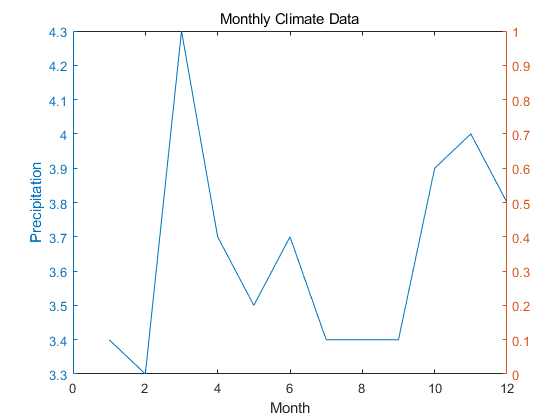

figure
yyaxis left
plot(monthnum,precip)
xlabel('Month')
ylabel('Precipitation')
title('Monthly Climate Data')

## Add Right y-Axis

Create a line plot for the temperature of each month using the *y*-axis on the right. The `yyaxis` `right` command activates the right *y*-axis.

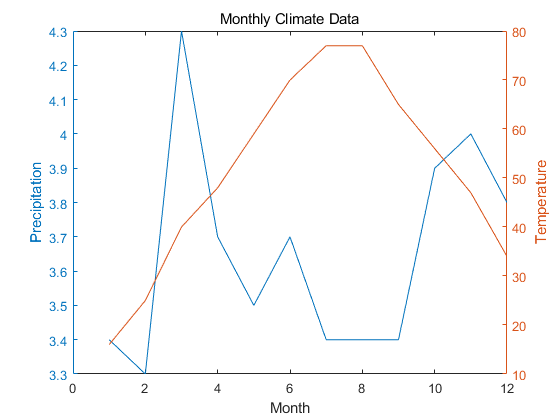

yyaxis right
plot(monthnum,temp)
ylabel('Temperature')

## Add Multiple Lines to Plot With Two y-Axes

To add multiple lines to the plot, use the `hold on` command followed by additional plot commands. The additional lines use the same color as the right *y*-axis and cycle through the line style order.

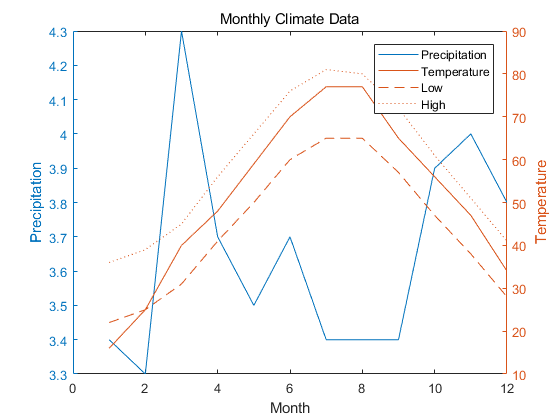

low = [22 25 31 41 50 60 ...
                65 65 57 47 38 28];
high = [36 39 45 56 66 76 ... 
                81 80 72 61 51 41];
hold on
plot(monthnum,low)
plot(monthnum,high)
ylabel('Temperature')
legend('Precipitation','Temperature','Low','High')
hold off

## Combining Visualization Types With Two y-Axes

With yyaxis, you can use a different plot type on each *y*-axis. For example, create a bar chart of precipitation by month.

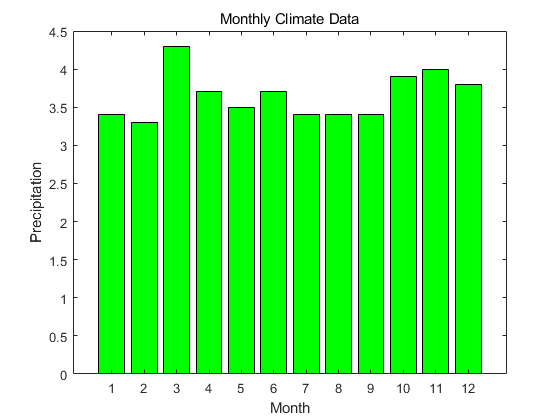

clf
bar(monthnum,precip,'FaceColor','g')
xlabel('Month')
ylabel('Precipitation')
title('Monthly Climate Data')

You can add a right *y*-axis to an existing chart with the `yyaxis right` command. The right *y*-axis uses the next color in the color order for the axes.

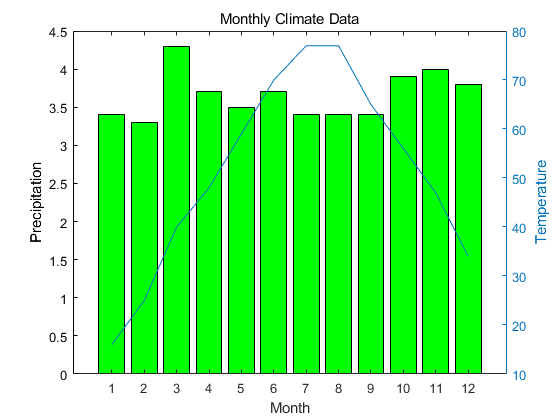

yyaxis right
plot(monthnum,temp)                            
ylabel('Temperature')

To adjust the limits of the left *y*-axis, use the `yyaxis left` command to activate the left side and then set the limits.

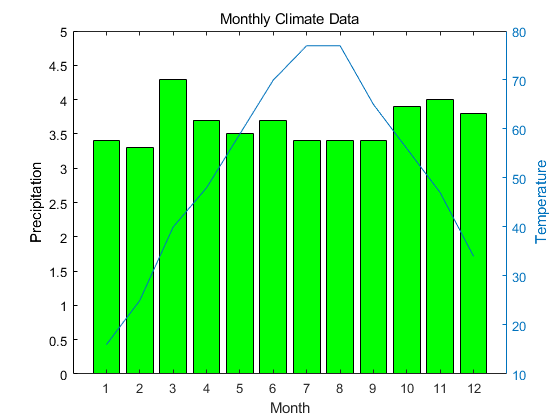

yyaxis left
ylim([0 5])
xlim([0 13])